## ANFIS for Load Prediction

choose Training Data

cd C:\dev\WPS3-EMS\API_service\Datasets\

% Get Price
Price_table = load("ElSpotPrice_kWh_okt24.mat");
Price_array = Price_table.elspotData.SpotPriceDKK; % Price
Price_array = flip(Price_array); % => first index first day

% Get Weather Data
Weather_table = load("WeatherData_okt24.mat");
Weather_array = table2array(Weather_table.WeatherData_table(:,2:end));
Weather_array = flip(Weather_array); % => first index first day

% get Time
time = flip(Weather_table.WeatherData_table.time);
time = datetime(time, 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss''Z''', 'TimeZone', 'UTC','Format','yyyy-MM-dd''T''HH');

% Get Load
Load_table = load("loadData_okt24.mat");
Load_array = Load_table.loadData_okt24(2).data.ConsumptionkWh;
Load_array = flip(Load_array);

disp('Files Loaded')

Files Loaded


% Create Previous Load array (shifted by 24h )
LoadPrev7d_array = circshift(Load_array,24*7); % day before
LoadPrev24h_array = circshift(Load_array,24); % day before
LoadPrev1h_array = circshift(Load_array,1); % 1h before

% Delete Due to longest shift
delay = 24*7;
LoadPrev7d_array = LoadPrev7d_array(delay:end,:);
LoadPrev24h_array = LoadPrev24h_array(delay:end,:); % Cut off First Day 
LoadPrev1h_array = LoadPrev1h_array(delay:end,:);
Weather_array = Weather_array(delay:end,:);
Price_array = Price_array(delay:end,:);
Load_array = Load_array(delay:end,:);
time = time(delay:end,:); % CUt off First Day

% Correlation betweenAverages
windowSize_temp = 24; % Size of the moving average window
Temp_ave = movmean(Weather_array(:,3), windowSize_temp);
windowSize_load = 24; % Size of the moving average window
LoadPrev24h_ave = movmean(LoadPrev1h_array, windowSize_load);
corrcoef([Temp_ave LoadPrev_ave])

ans =     1.0000   -0.5688
   -0.5688    1.0000


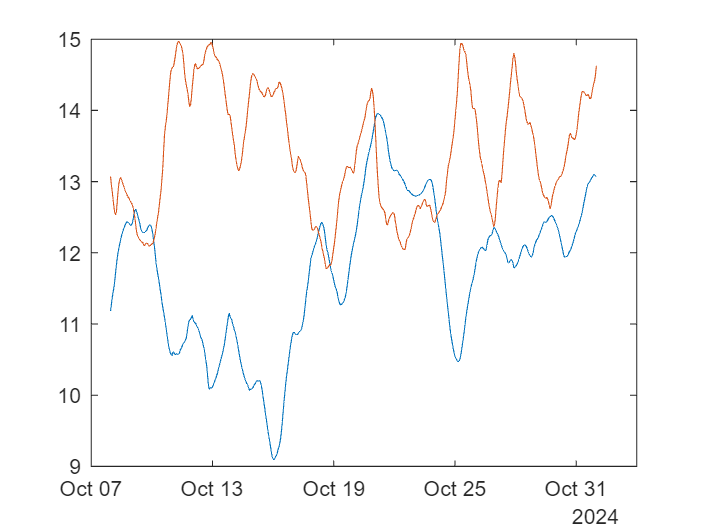

plot(time(:),[Temp_ave  LoadPrev_ave/200])

% Calculate Correlation of variables to Load Consumption
CORR = corrcoef([Price_array Weather_array Temp_ave LoadPrev7d_array LoadPrev24h_array LoadPrev1h_array LoadPrev_ave Load_array]);
columnNames = ["Price", "Humidity", "Solar", "Temp", "Wind", "Temp_ave" "Load-7d" "Load-24h" "Load-1h" "Load_ave", "Load"];
% Convert the data into a table
CORR_table = array2table(CORR(end, :), 'VariableNames', columnNames);
disp(CORR_table);

      Price      Humidity     Solar        Temp        Wind      Temp_ave    Load-7d    Load-24h    Load-1h    Load_ave    Load
    _________    ________    ________    ________    ________    ________    _______    ________    _______    ________    ____

    -0.021106    -0.14304    -0.43664    -0.38777    0.079504    -0.26699    0.54321    0.64986     0.8576     0.47672      1  



% Convert to matrix for taining
Data = [];
%Data(:,width(Data)+1) = Weather_array(:,2); % Weather (Solar = 2) (Temp =3) 
%Data(:,width(Data)+1) = Temp_ave;
%Data(:,width(Data)+1) = LoadPrev7d_array; % Past Consumpotion 24h
%Data(:,width(Data)+1) = LoadPrev24h_array; % Past Consumpotion 24h
Data(:,width(Data)+1) = LoadPrev1h_array; % Past Consumpotion 24h
Data(:,width(Data)+1) = LoadPrev24h_ave;
Data(:,width(Data)+1) = Load_array; % Current Consumpotion
size(Data)

ans =    578     3


corrcoef(Data)

ans =     1.0000    0.4791    0.8576
    0.4791    1.0000    0.4767
    0.8576    0.4767    1.0000


Create Training and Testing data in form of an array

x = Data(:,1:end-1);
y = Data(:,end);
% Divide into Training and Testing Data
sizeOfTrainingData = 0.9 ; % [80%] of the Data
DataSplit_index = round(length(Data)*sizeOfTrainingData)

DataSplit_index = 520

trnData = Data(1:DataSplit_index,:);
chkData = Data(DataSplit_index+1:end,:);

## Build Initial Fuzzy System

%Options For GENFIS
number_Inputs = width(Data)-1;
number_MF = 3;
opt = genfisOptions('GridPartition');
opt.NumMembershipFunctions = number_MF * ones(1,number_Inputs);
opt.InputMembershipFunctionType = repmat("gaussmf", 1, number_Inputs);

Create an initial Sugeno FIS object for training using the `genfis` function with grid partitioning.

fis = genfis(trnData(:,1:end-1),trnData(:,end),opt);

The number of FIS inputs and outputs corresponds to the number of columns in the input and output training data, four and one, respectively.

By default, `genfis` creates two generalized bell membership functions for each of the four inputs. The initial membership functions for each variable are equally spaced and cover the whole input space.

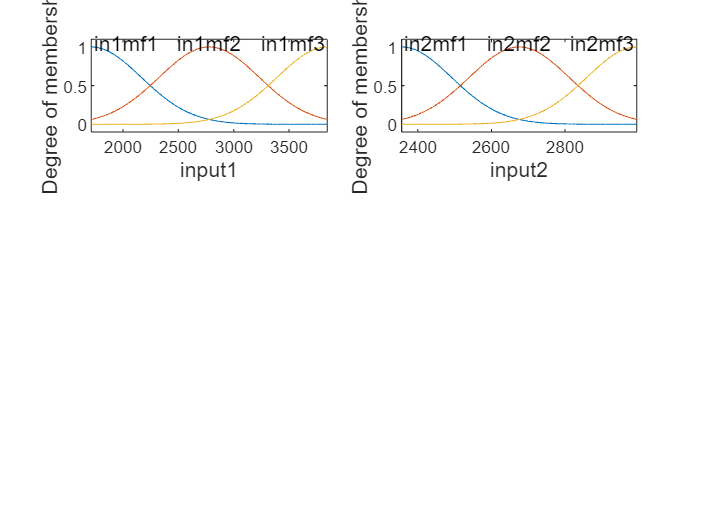

figure
for i =1:number_Inputs
    subplot(3,2,i)
    plotmf(fis,'input',i)
end

The generated FIS object contains $2^4$ = 16 fuzzy rules with 104 parameters (24 nonlinear parameters and 80 linear parameters). To achieve good generalization capability, it is important that the number of training data points be several times larger than the number parameters being estimated. In this case, the ratio between data and parameters is approximately five (500/104), which is a good balance between fitting parameters and training sample points.

## Train ANFIS Model

To configure training options, create an `anfisOptions` option set, specifying the initial FIS and validation data.

options = anfisOptions('InitialFIS',fis,'ValidationData',chkData);
options.EpochNumber = 100;

Train the FIS using the specified training data and options.

[fis1,error1,ss,fis2,error2] = anfis(trnData,options);

ANFIS info:
	Number of nodes: 35
	Number of linear parameters: 27
	Number of nonlinear parameters: 12
	Total number of parameters: 39
	Number of training data pairs: 520
	Number of checking data pairs: 58
	Number of fuzzy rules: 9


Start training ANFIS ...

1 	 202.571 	 217.651
2 	 202.571 	 217.651
3 	 202.571 	 217.65
4 	 202.571 	 217.651
Step size increases to 0.011000 after epoch 5.
5 	 202.571 	 217.65
6 	 202.571 	 217.651
7 	 202.571 	 217.65
8 	 202.571 	 217.651
Step size increases to 0.012100 after epoch 9.
9 	 202.571 	 217.651
10 	 202.571 	 217.652
11 	 202.571 	 217.652
12 	 202.571 	 217.652
Step size increases to 0.013310 after epoch 13.
13 	 202.571 	 217.652
14 	 202.571 	 217.653
15 	 202.571 	 217.652
16 	 202.571 	 217.653
Step size increases to 0.014641 after epoch 17.
17 	 202.57 	 217.653
18 	 202.57 	 217.653
19 	 202.57 	 217.653
20 	 202.57 	 217.653
Step size increases to 0.016105 after epoch 21.
21 	 202.57 	 217.654
22 	 202.57 	 217.654
23 	 202.57 	 2

`fis1` is the trained fuzzy inference system for the training epoch where the training error is smallest. Since you specified validation data, the fuzzy system with the minimum checking error, `fis2`, is also returned. The FIS with the smallest checking error shows the best generalization beyond the training data.

Plots the membership functions for the trained system.

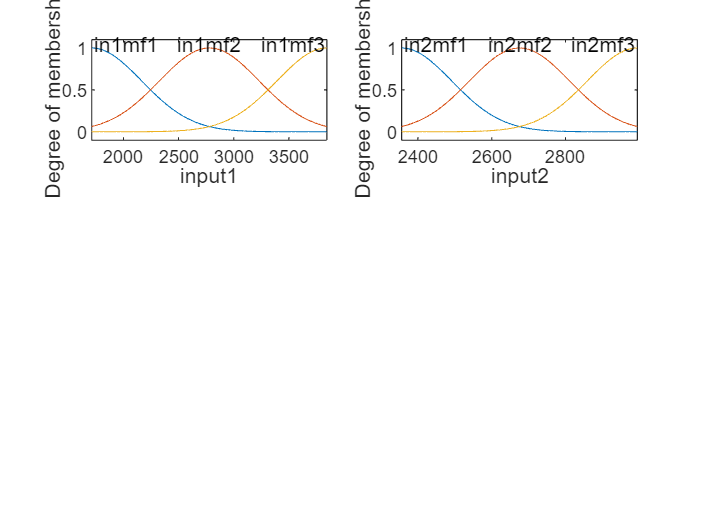

figure
for i =1:number_Inputs
    subplot(3,2,i)
    plotmf(fis2,'input',i)
end

## Plot Errors Curves

Plot the training and checking error signals.

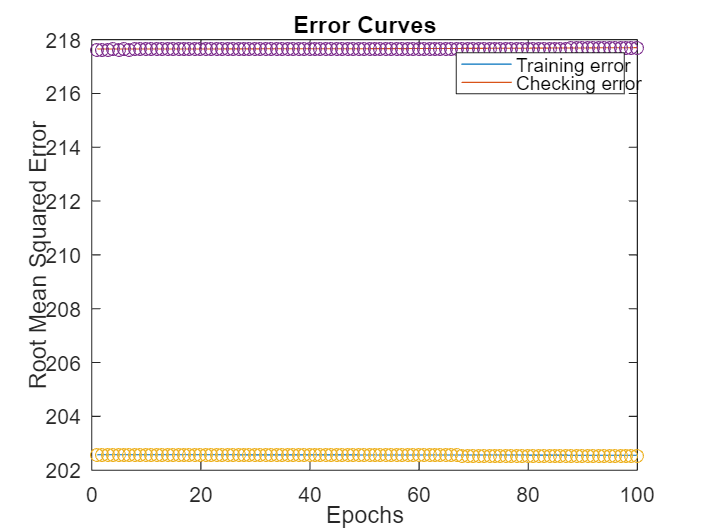

figure
plot([error1 error2])
hold on
plot([error1 error2],'o')
legend('Training error','Checking error')
xlabel('Epochs')
ylabel('Root Mean Squared Error')
title('Error Curves')

## Compare Original and Predicted Series

To check prediction capability of the trained system, evaluate the fuzzy system using the training and checking data, and plot the result alongside the original

y_pred = evalfis(fis2,[trnData(:,1:end-1); chkData(:,1:end-1)]);

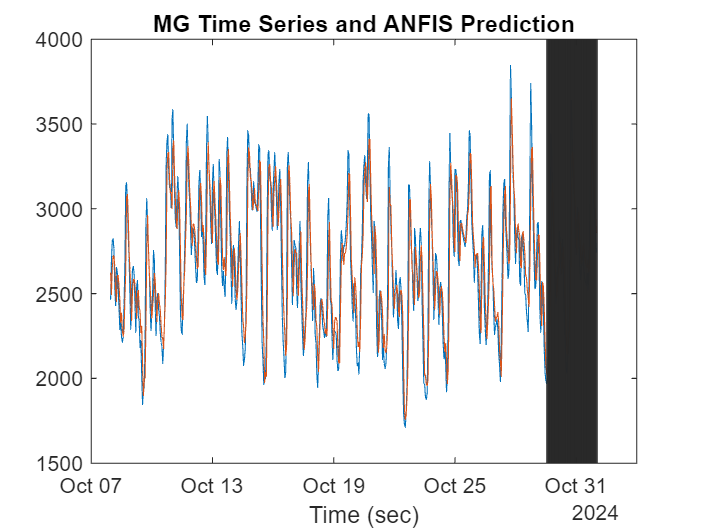

figure;
plot(time,[y y_pred])
xline(time(DataSplit_index:end),'LineWidth', 1.5)
xlabel('Time (sec)')
title('MG Time Series and ANFIS Prediction')

The predicted series is similar to the original series.

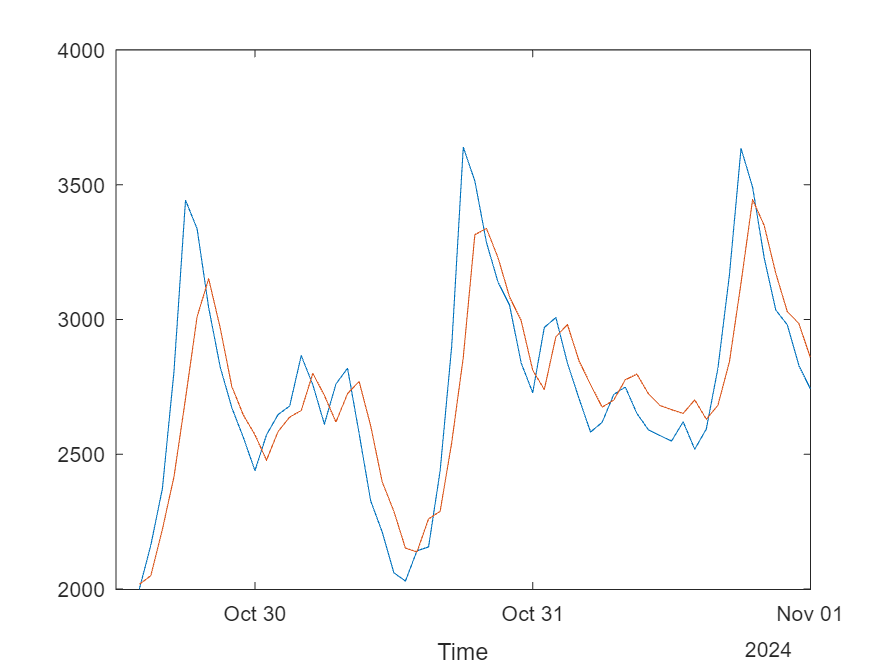

% zoom
plot(time(DataSplit_index:end),[y(DataSplit_index:end) y_pred(DataSplit_index:end)])
xlabel('Time')

Calculate and plot the prediction error.

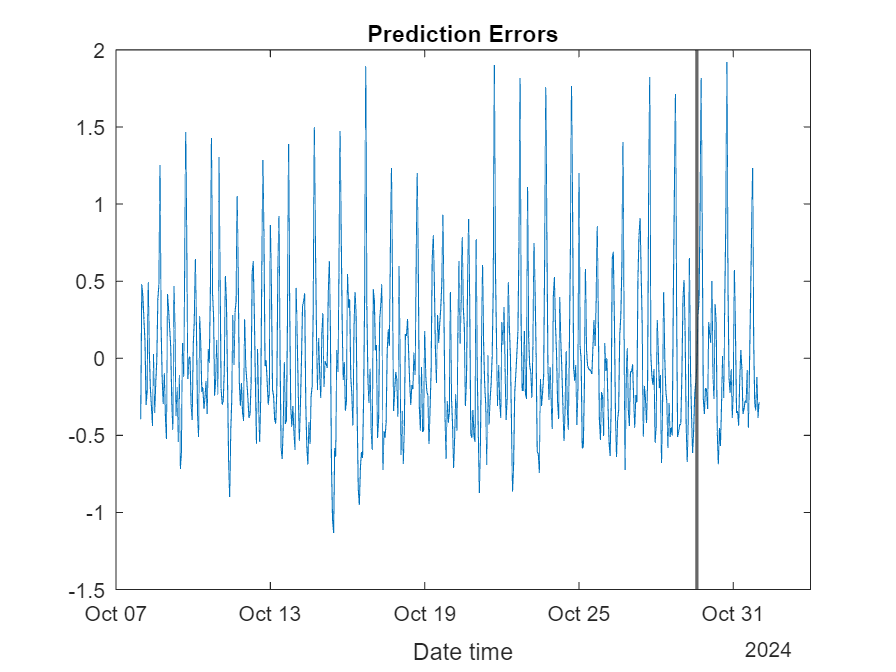

figure;
diff = y - y_pred;
diff_norm = diff / std(y);
plot(time,diff_norm)
xline(time(DataSplit_index),'LineWidth', 1.5)
xlabel('Date time')
title('Prediction Errors')

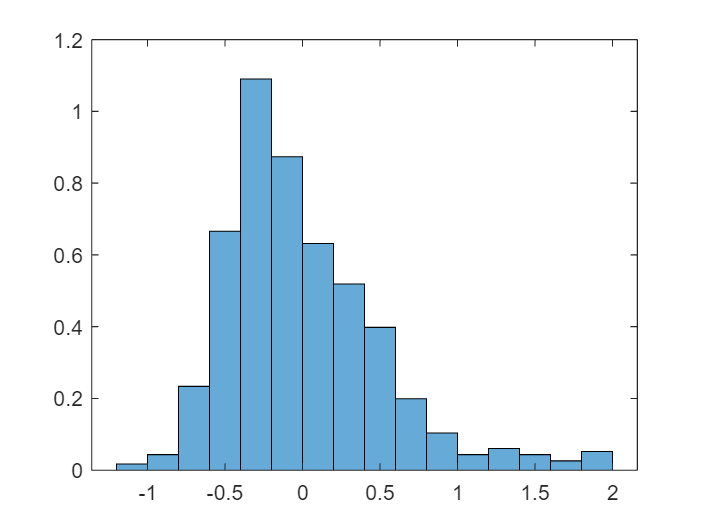

histogram(diff_norm,'Normalization','pdf');

RMSE = rmse(y_pred,y)/std(y)

RMSE = 0.5034

The scale of the prediction error plot is about one-hundredth of the scale of the time-series plot. In this example, you trained the system for only 10 epoch. Training for additional epochs can improve the training results.

Copyright 2018-2022 The MathWorks, Inc.